run('BASIC.m')

sys_discret =
 
  0.0076672 (z-0.7239) (z-0.8621)
  -------------------------------
  (z-1.109) (z-0.6048) (z-0.5835)
 
Sample time: 0.094282 seconds
Discrete-time zero/pole/gain model.



## generate Data

Question_mark='Q213';
[uc,t,Status,tfinal]=Datagen(0,T_s,200);

Status = '_No NOISE_'

Titlework=[Question_mark,Status]

Titlework = 'Q213_No NOISE_'

#### General Input

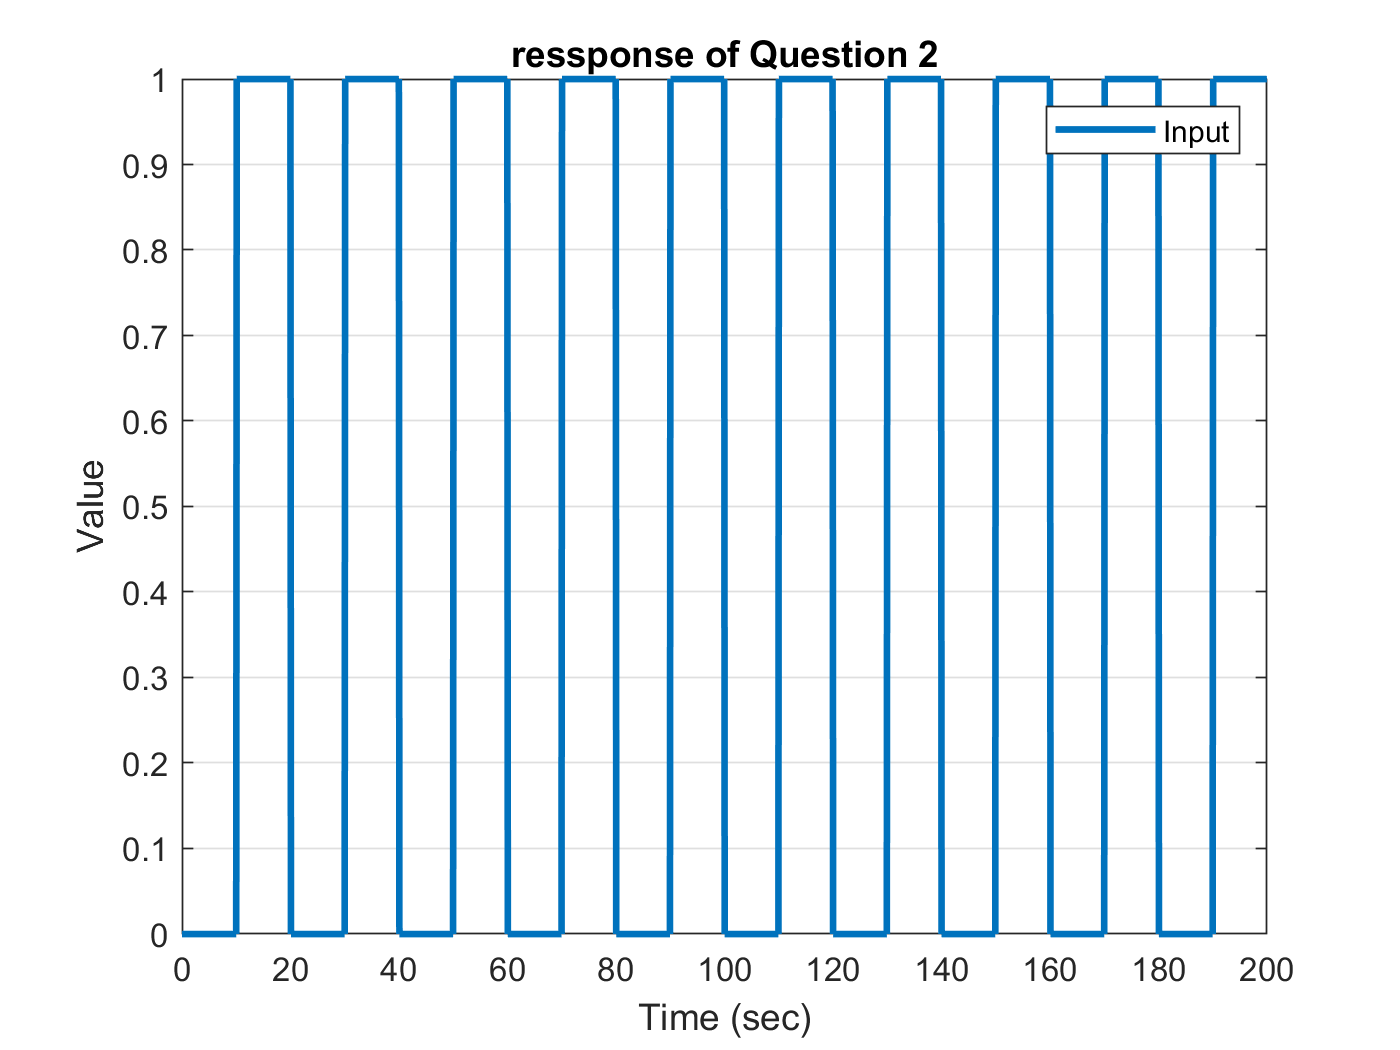

y = lsim(sys_discret  ,uc ,t);
plot(t,uc ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;
print(gcf,[Titlework , num2str(plot_counter) ' Refrence .png'],'-dpng','-r400');

plot_counter=plot_counter+1;

## Assumption

%choose number of parameters
Parameters_in_den=3

Parameters_in_den = 3

Parameters_in_num=3

Parameters_in_num = 3

degre_canselled_zero=0

degre_canselled_zero = 0

A_m=poly([0.5 0.5 0.2]);

deg_A=Parameters_in_num+1;
deg_B=Parameters_in_den  ;
Nv=Parameters_in_num+Parameters_in_den;
deg_B_plus =degre_canselled_zero+1;
Deg_B_minus=deg_B-deg_B_plus;
Deg_A_o=deg_A-deg_B_plus-1;
A_o=[1 zeros(1,Deg_A_o)];
A_c_prim=conv(A_m,A_o);

##     RLS


theta(1:Nv,1:40) = ones(Nv,40) ;
P = 1e12*eye(Nv) ;
phi=[];
N = numel(y) ;
u_cont=uc;
%for i = (max(Parameters_in_num,Parameters_in_den)+1):N
for i = (deg_A+deg_B):N
    phi(:,i) = [(y(i-1:-1:i-Parameters_in_den))' , (u_cont(i-1:-1:i-Parameters_in_num))']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 

    A=[1 -theta(1:Parameters_in_num ,end)'];
    B=theta((Parameters_in_num+1):end,end)';
    if degre_canselled_zero==0
        B_plus=1;
        B_minus=B;
        betaa=sum(A_m)/sum(B);
        B_m=betaa*B;
    end
    A_c=conv(A_c_prim,B_plus);

##         MDPP WNZC

    [R_prim,Si] = Diophantine(A,B ,A_c_prim);
    S(i,:)=Si;
    T(i,:)=conv(betaa,A_o);
    R(i,:)=conv(R_prim,B_plus);

    var1=conv(B,T(i,:));      narv1=numel(var1)      ;
    var2=A_c(2:end)     ;     narv2=numel(A_c(2:end));
    var3=conv(A,T(i,:)) ;     narv3=numel(var3)      ;
    
    y(i)     =var1*uc(i:-1:i-narv1+1)-var2*y(i-1:-1:i-narv2);
    u_cont(i)=var3*uc(i:-1:i-narv3+1)-var2*u_cont(i-1:-1:i-narv2);
end

## General Input v.s. Output

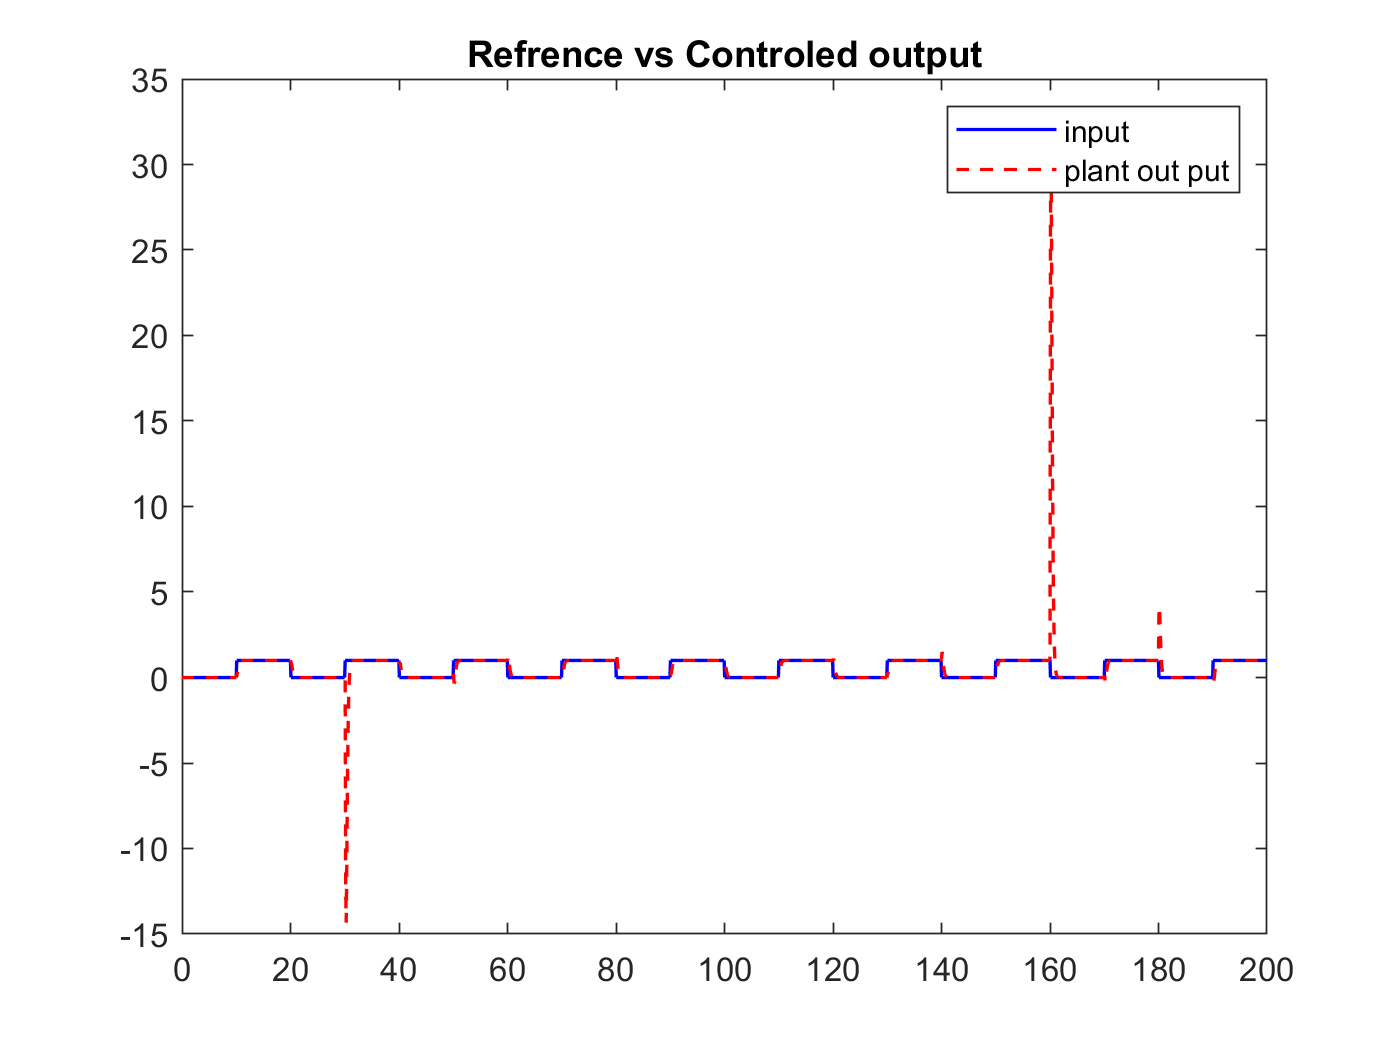

plot(t,uc,'b',t,y,'r--','LineWidth',1)
title('Refrence vs Controled output')
legend('input','plant out put')
print(gcf,[Titlework , num2str(plot_counter) ' Refrence vs Controled output.png'],'-dpng','-r400');

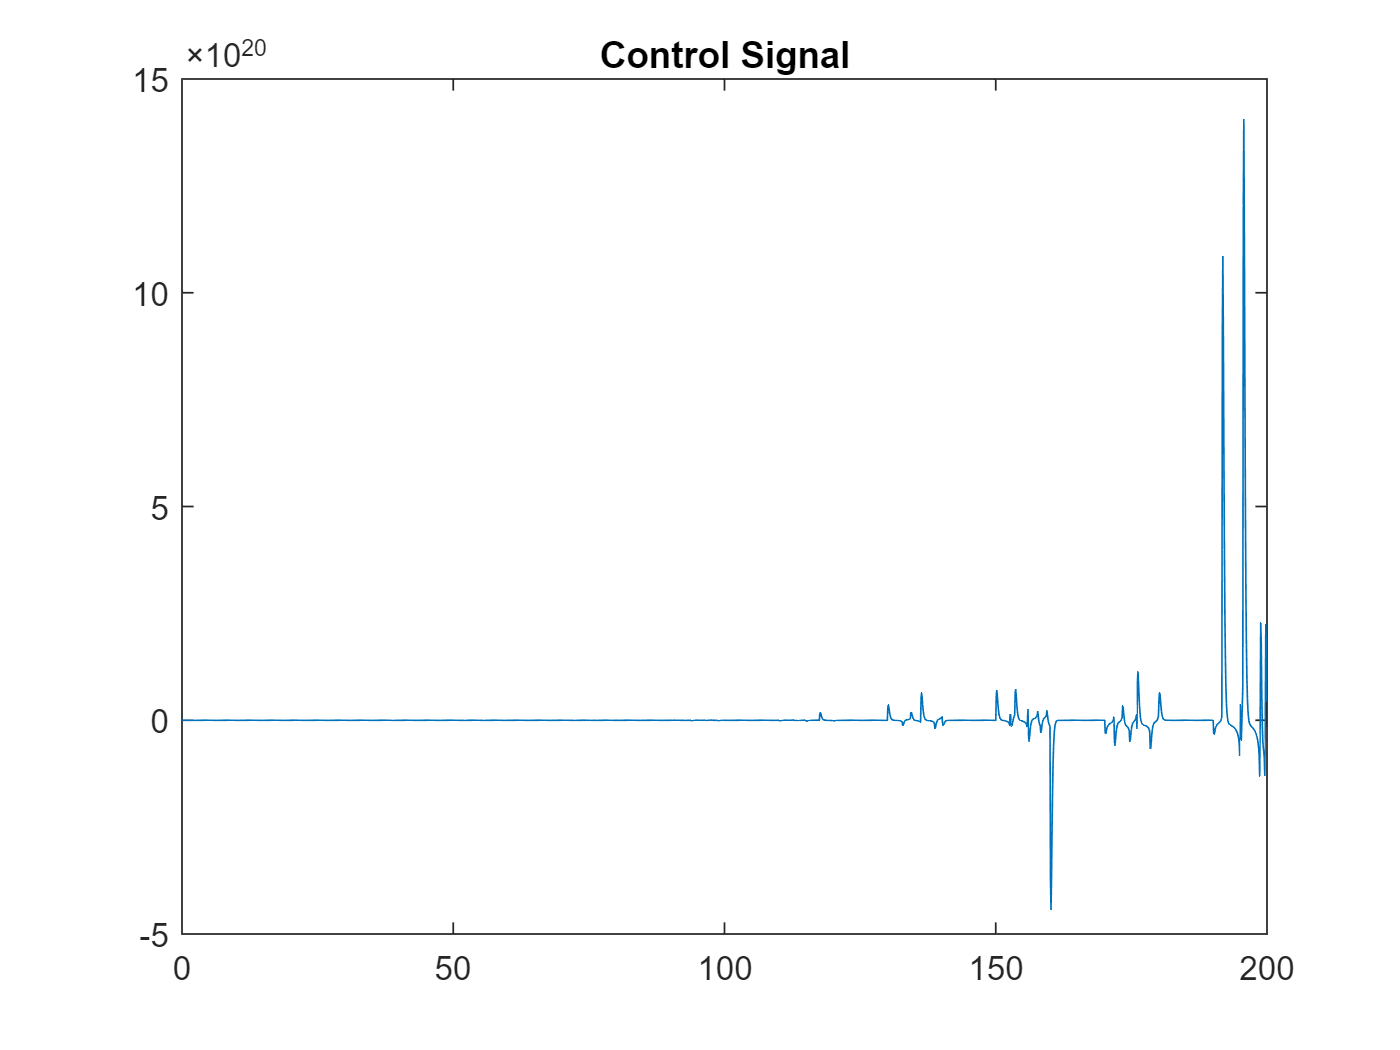

plot_counter=plot_counter+1;

plot(t,u_cont)
title('Control Signal')
print(gcf,[Titlework , num2str(plot_counter) ' Control Signal.png'],'-dpng','-r400');

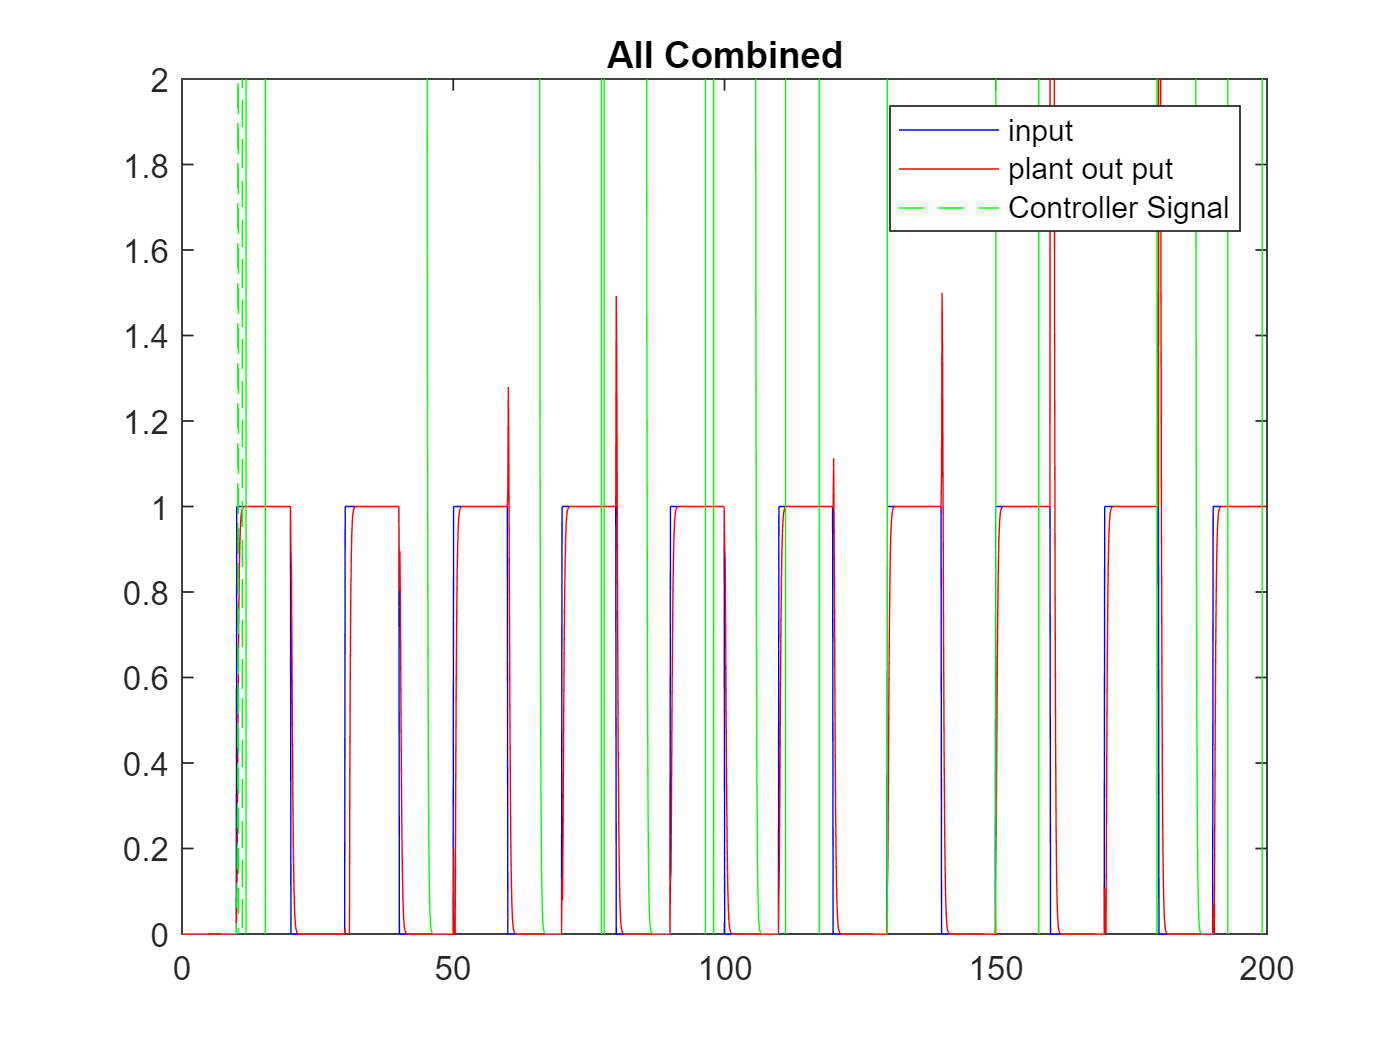

plot_counter=plot_counter+1;

plot(t,gensig('square' , tfinal/10 , tfinal ,T_s),'b',t,y,'r',t,u_cont,'g--','LineWidth',0.25)
title('All Combined')
legend('input','plant out put','Controller Signal')
xlim([0 tfinal])
ylim([0 2])
print(gcf,[Titlework , num2str(plot_counter) ' All Combined.png'],'-dpng','-r600');

plot_counter=plot_counter+1;

RLS Convergence of R UND S

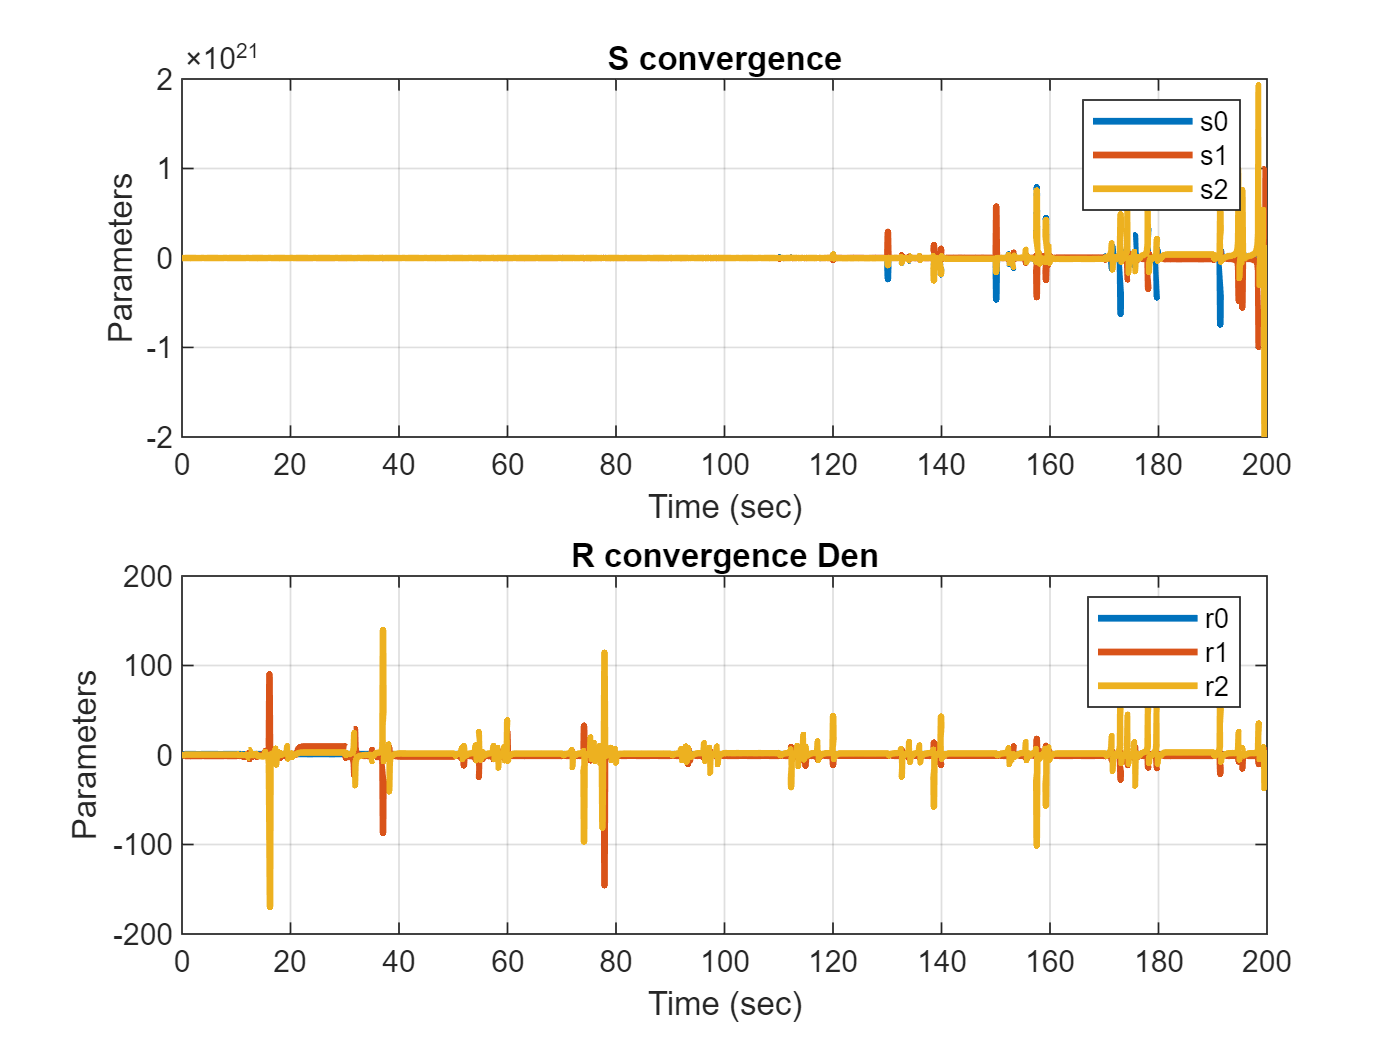

subplot(2,1,1)
    for i=1:deg_A-1
        legend_names{i} = ['s' num2str(i)-1 ''];
    end
    plot(t ,S(:,:), 'LineWidth' , 2) ;
    legend(legend_names)
    xlabel('Time (sec)') ;
    ylabel('Parameters') ;
    title('S convergence') ;
    grid on
subplot(2,1,2)
    for i=1:deg_A-1
        legend_names{i} = ['r' num2str(i)-1 ''];
    end
    plot(t ,R(:,:), 'LineWidth' , 2) ;
    legend(legend_names)
    xlabel('Time (sec)') ;
    ylabel('Parameters') ;
    title('R convergence Den') ;
    grid on
print(gcf,[Titlework , num2str(plot_counter) ' RLS Convegence.png'],'-dpng','-r400');